# 2D Heat Equation

clc;

Parameters

a_x=0; b_x=1;
a_y=0; b_y=1;
T=0.5;
u0=@(x,y)sin(pi*x).*sin(pi*y);
u_exact=@(x, y, t)exp(-2*pi^2*t).*sin(pi*x).*sin(pi*y);

Grid

m=20;
x=linspace(a_x, b_x, m+1);
y=linspace(a_y, b_y, m+1);
h=(b_x-a_x)/m;
dt = T/m;
[x_coord, y_coord]=meshgrid(x, y); 
%x_coord, y_coord contains the x, y coordinates of each grid points.
x_coord=x_coord';
y_coord=y_coord';

Initialize the grid function $U^0_{ij}= u_0(x_i, y_j)$.

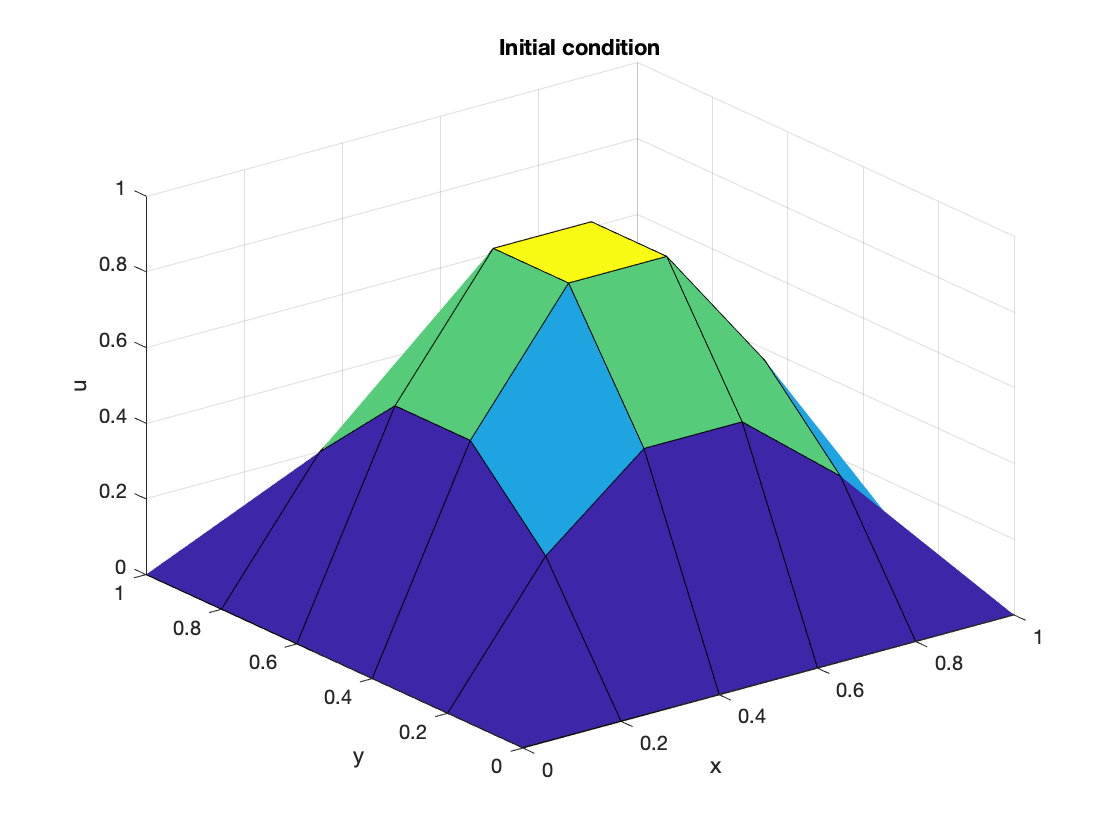

U=u0(x_coord, y_coord);
figure
surf(x_coord, y_coord, U)
xlabel('x'), ylabel('y'), zlabel('u')
title('Initial condition')

## 2D Crank-Nicolson Method

Generate the Matrix A for the semi discrete problem

                                                        
$$\frac{d}{dt}\vec{U}(t)=A \vec{U}(t)$$


where

$A=\frac{1}{h^2 }\left\lbrack \begin{array}{cccc}
T & I & \cdots \; & O\\
I & T & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & I\\
O & \cdots  & I & T
\end{array}\right\rbrack$and $T=\left\lbrack \begin{array}{cccc}
-4 & 1 & \cdots  & 0\\
1 & -4 & \ddots  & \vdots \\
\vdots  & \ddots  & \ddots  & 1\\
0 & \cdots  & 1 & -4
\end{array}\right\rbrack$.

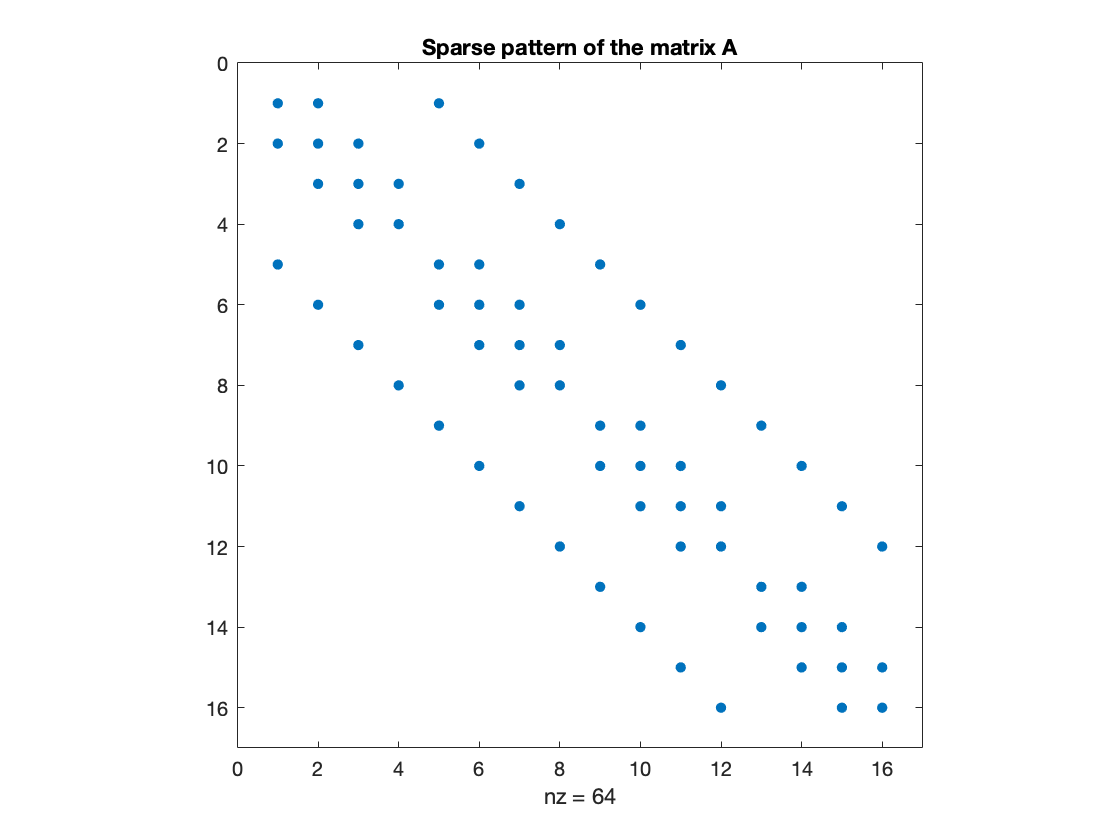

I=eye(m-1);
e=ones(m-1,1);
mat_T=spdiags([e, -4*e, e], [-1,0,1], m-1, m-1);
S=spdiags([e, e], [-1, 1], m-1, m-1);
A=(kron(I, mat_T)+kron(S, I))/h^2;
%display the sparse pattern of the matrix A
spy(A)
title('Sparse pattern of the matrix A')

Output the first row of A and get an idea how MATLAB stores the matrix in the sparse storage.

disp(A(1,:))

   (1,1)    -100.0000
   (1,2)      25.0000
   (1,5)      25.0000



March in time with the trapezoidal method

                                                
$$\left(I-\frac{\Delta t}{2} A\right)\vec{U}^{n+1}=\left(I+\frac{\Delta t}{2} A\right) \vec{U}^{n}$$


where $\vec{U}=[U(:,1); U(:, 2); ...; U(:,m-1)].$

%Reordering the unknowns in the rowwise ordering and reshape the unknown matrix into a vector. hint: reshape
U = reshape(U(2:end-1,2:end-1),[],1);
%Generate matrices I-dt/2*A and I+dt/2*A and store them in the sparse storage. hint: speye(m) gives identity matrix in the sparse structure.
LHS = speye((m-1)^2) - (dt/2)*A;
RHS = speye((m-1)^2) + (dt/2)*A;

%March in time and measure the execution time of the time marching. Hint: tic; .... toc;
%In each time step, solve the linear system with the direct solver.
step = T/dt;
tic;
for i = 1:step
    Unew = LHS\(RHS*U);
    U = Unew;
end
time_CNM = toc();

In 2D, the $\|\cdot\|_{2, h}$ norm is defined by  


$$\| \vec{U}-\vec{u}\|_{2, h} =\sqrt{ h^2\sum_{i=0}^{m}\sum_{j=0}^m |U_{i, j}-u(x_i, y_j)|^2 $$


%Calculate the error in this norm.
tspan = 0:dt:T;
Exact = u_exact(x_coord,y_coord,T);
Exact = reshape(Exact(2:end-1,2:end-1),[],1);
error_CNM = norm(U-Exact)*h;

## LOD Method

In each time step, the LOD method consists of two substeps.

        
$$\left(I-\frac{\Delta t}{2} A_x\right)\vec{U}_{:,  j}=\left(I+\frac{\Delta t}{2} A_x\right)\vec{U}_{:, j}, \quad j=1, ..., m-1,\\
\left(I-\frac{\Delta t}{2} A_y\right)(\vec{U}_{i,  :})^T=\left(I+\frac{\Delta t}{2} A_y\right)(\vec{U}_{i, :})^T, \quad i=1, ..., m-1.\\$$


%Generate the matrices A, I-dt/2*A, and I+dt/2*A. Store them in the sparse storage.
A = diag(-2*ones(1,m-1))+diag(ones(1,m_2),1)+diag(ones(1,m_2),-1);
A = (1/h^2)*A;
A = sparse(A);
LHS = speye(m-1)-(dt/2)*A;
RHS = speye(m-1)+(dt/2)*A;
%March in time and measure the execution time.
tic;
for i=1:step
    for j=1:step
        U_temp = LHS\(RHS*U(:,j));
    end
end
%TODO

%Calculate the error in the l_{2,h} norm.
%TODO